%Load source audio
%Options: gong, chirp, handel, laughter, splat, train

load chirp
y1=y; Fs1=Fs;


load train
y2=y; Fs2=Fs;

%Must be same size
lengths=[length(y1),length(y2)];
%l = 1000;
l=min(lengths);
%Unmixed matrix
S=[y1(1:l,:), y2(1:l,:)];

%Mixes withOUT random offset
%A1 = randn(2);
A1 = [2, 4.9; 5.9, 3];
M=S*A1; %+randn(size(S));
M = M';

[Mw, whiteningMatrix, dewhiteningMatrix, means] = preprocessing(M);
%Mw = whitening2(M);

% %Fourier transform on whitened data
% dftW=fftshift(fft(Mw(1,:)));
% magW=abs(dftW);
% 
% dftM=fftshift(fft(M(1,:)));
% magM=abs(dftM);
% 
% Fs=8192; %sampling rate
% Nx=length(Mw(1,:));
% fx=linspace(-Fs/2, Fs/2 -Fs/Nx, Nx);
% subplot(1,2,1)
% plot(fx,magW)
% subplot(1,2,2)
% plot(fx,magM)

[A, W] = icaRounds(whiteningMatrix, dewhiteningMatrix, Mw, means);

icasig = W * M + (W * means) * ones(1, l);

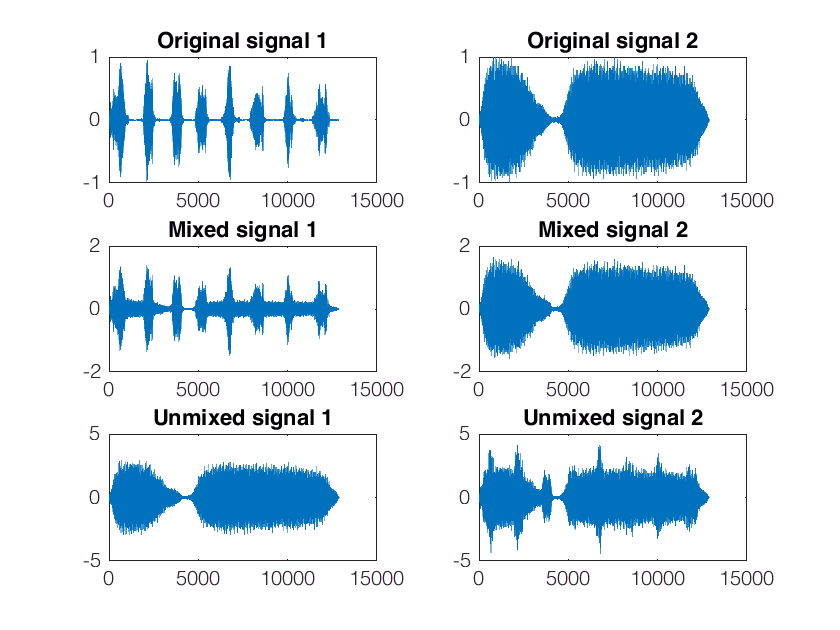

%Plot these losers
subplot(3,2,1)
plot(S(:,1))
title('Original signal 1');

subplot(3,2,2)
plot(S(:,2))
title('Original signal 2');

subplot(3,2,3)
plot(M(1,:))
title('Mixed signal 1');

subplot(3,2,4)
plot(M(2,:))
title('Mixed signal 2');

subplot(3,2,5)
plot(icasig(1,:))
title('Unmixed signal 1');

subplot(3,2,6)
plot(icasig(2,:))
title('Unmixed signal 2');